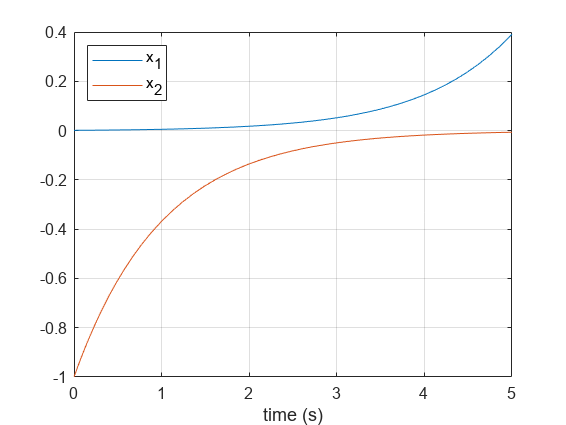

clear; close all;

x10 = 0.001;
x20 = -1;
[t,y] = ode45(@f, [0 5], [x10;x20;zeros(6,1)]);

figure
plot(t,y(:,1:2))
legend('x_1','x_2','Location','northwest')
grid on
xlabel('time (s)')

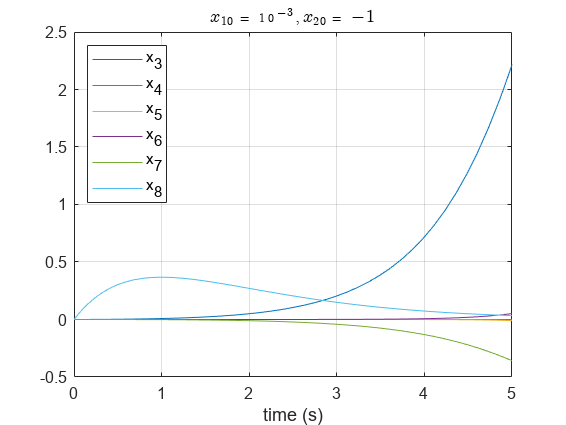


figure
plot(t,y(:,3:end))
legend('x_3','x_4','x_5','x_6','x_7','x_8','Location','northwest')
grid on
xlabel('time (s)')
title('$x_{10}= 10^{-3}, x_{20}=-1$','Interpreter','latex')

function [dydt] = f(~,y)
dydt = zeros(8,1);
x1 = y(1);
x2 = y(2);
x3 = y(3);
x4 = y(4);
x5 = y(5);
x6 = y(6);
x7 = y(7);
x8 = y(8);

s = 1/(1+x1^2) - x2;

dydt(1) = atan(x1)-x1*x2;
dydt(2) = -x2;
dydt(3) = s*(x1+x3) - x1*x4;
dydt(4) = -x4;
dydt(5) = s*x5-x1*x6;
dydt(6) = -x6+x1^2;
dydt(7) = s*x7 - x1*x8;
dydt(8) = -x8-x2;
end